# Redes Neuronales

### Tarea 4: Random Forest 

**Realizado por: **David Fabián Cevallos Salas

**Fecha: **2023-07-27

En la presente tarea analizaremos mediante Random Forests los datasets Computer Hardware, carsmall y Tratamiento Regresion para compararlos con los modelos de regresión logrados a través de un único árbol de decisión.

### Dataset Computer Hardware

% Ejercicio 1: Dataset Computer Hardware
clc; 
clear;
close all;
rng(0);
warning("off","all")

fprintf("\n----------------------------------------------")


----------------------------------------------

fprintf("\nEjercicio 1: Dataset Computer Hardware")


Ejercicio 1: Dataset Computer Hardware

fprintf("\n----------------------------------------------")


----------------------------------------------


----------------------------------------------
Resultados para Fold Nro. 1
----------------------------------------------
Valor MSE (Regression tree) = 7907.7597
Valor MSE (Random forest) = 1165.0437
Diagrama de árbol de regresión

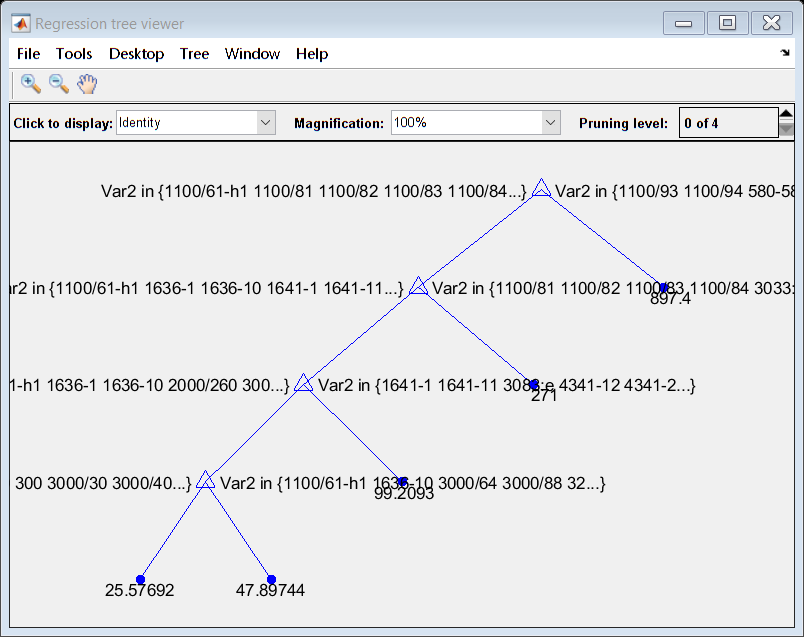

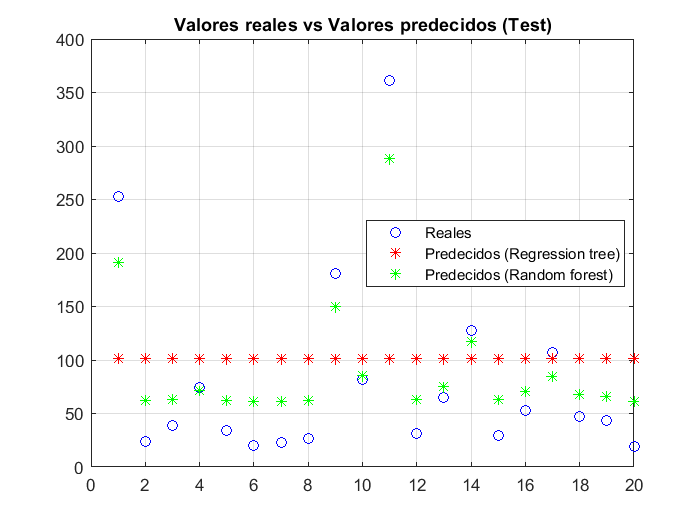


----------------------------------------------
Resultados para Fold Nro. 2
----------------------------------------------
Valor MSE (Regression tree) = 8578.8081
Valor MSE (Random forest) = 1573.8711
Diagrama de árbol de regresión

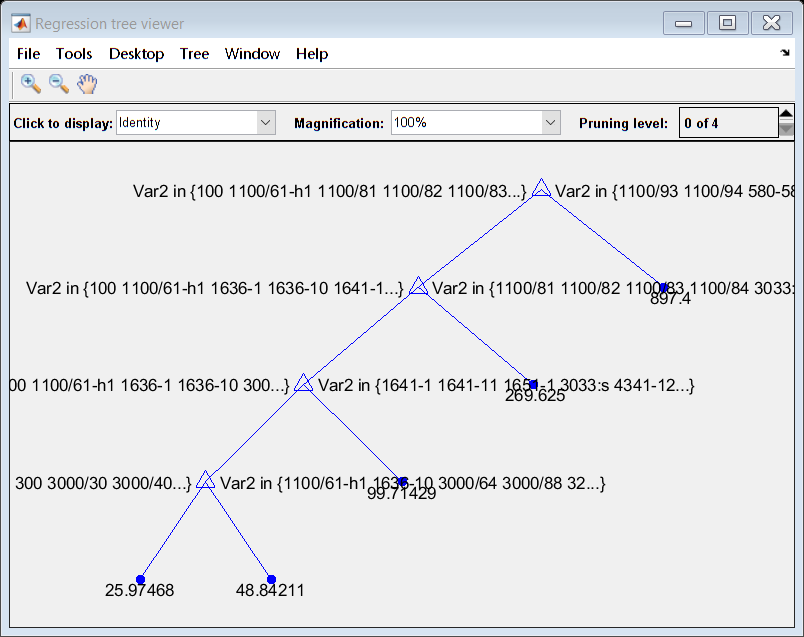

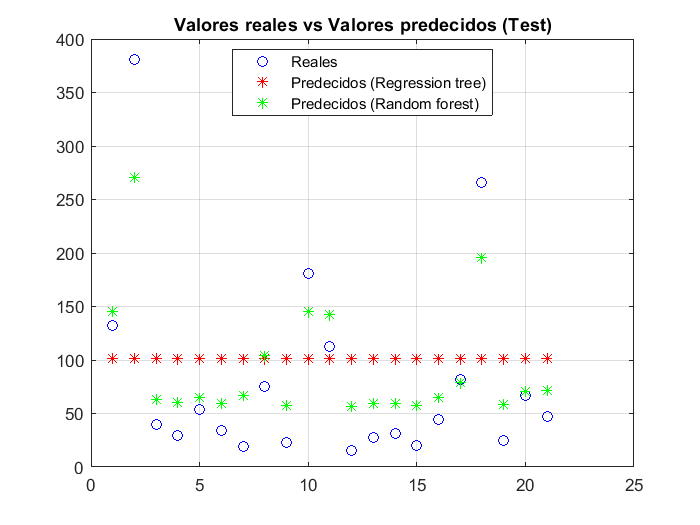


----------------------------------------------
Resultados para Fold Nro. 3
----------------------------------------------
Valor MSE (Regression tree) = 8575.9317
Valor MSE (Random forest) = 1341.5024
Diagrama de árbol de regresión

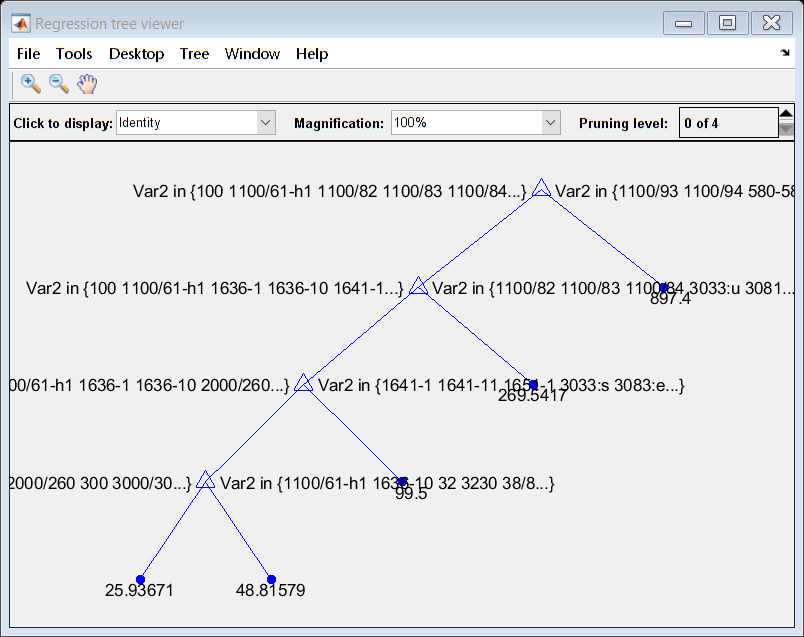

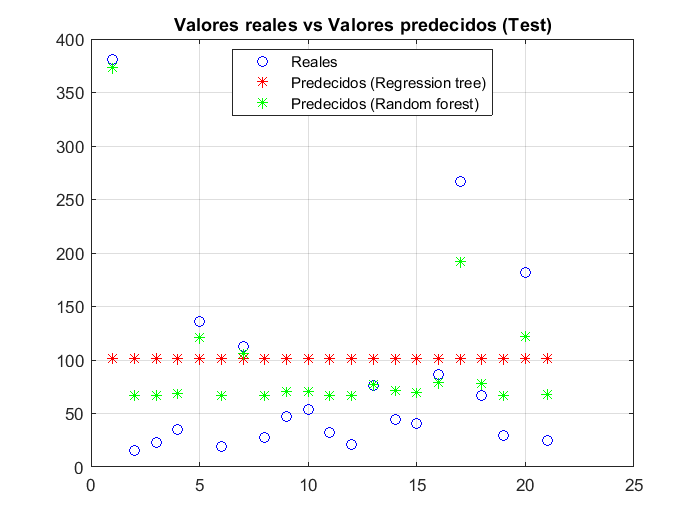


----------------------------------------------
Resultados para Fold Nro. 4
----------------------------------------------
Valor MSE (Regression tree) = 8622.5662
Valor MSE (Random forest) = 1903.0694
Diagrama de árbol de regresión

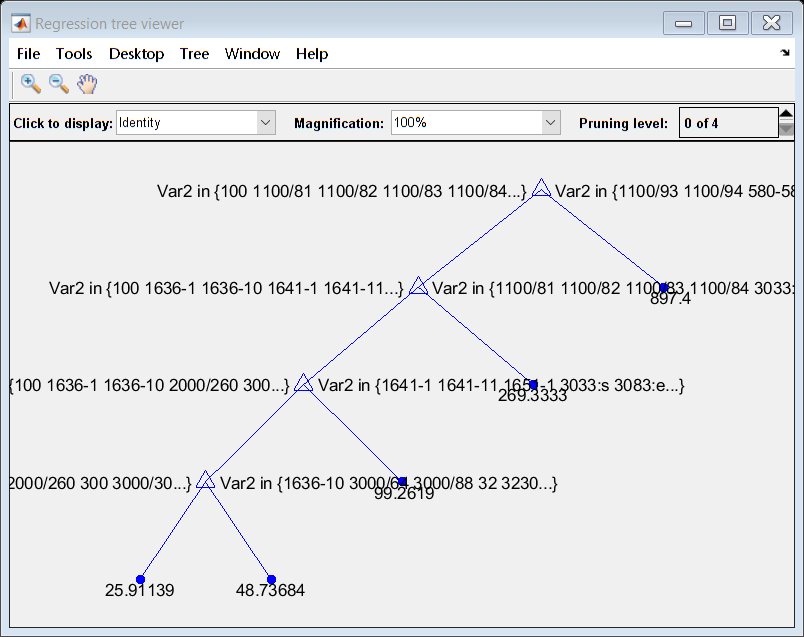

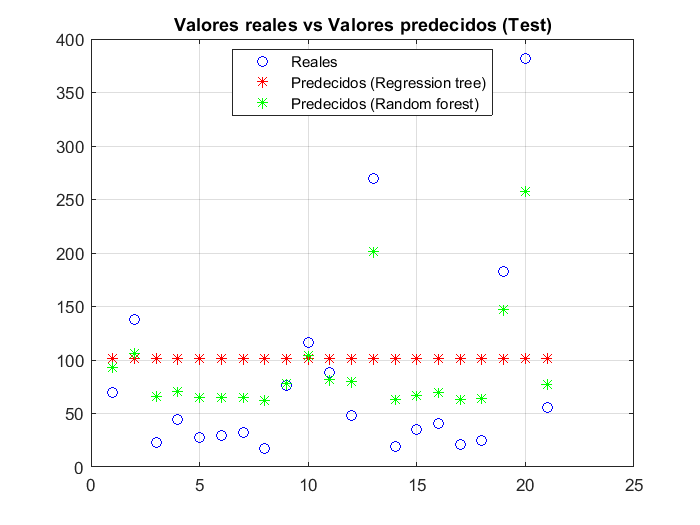


----------------------------------------------
Resultados para Fold Nro. 5
----------------------------------------------
Valor MSE (Regression tree) = 9979.7456
Valor MSE (Random forest) = 1338.9594
Diagrama de árbol de regresión

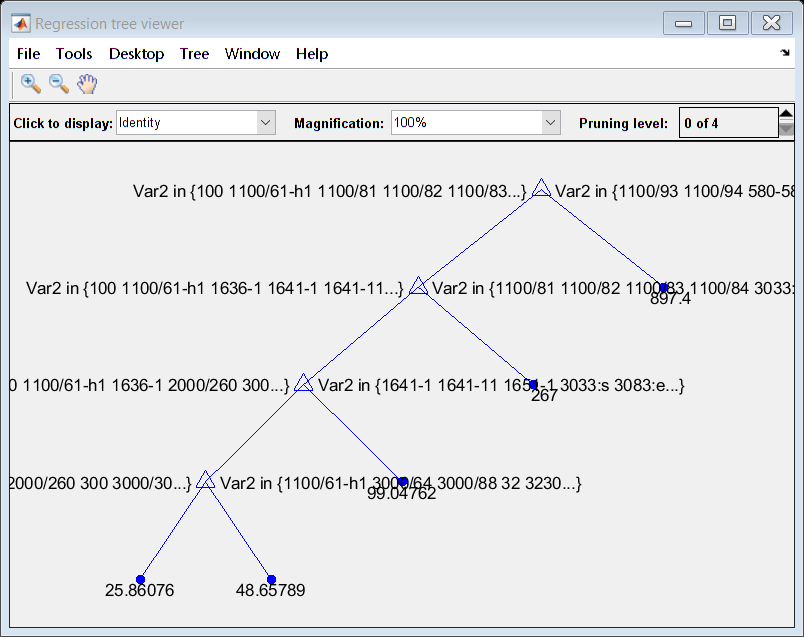

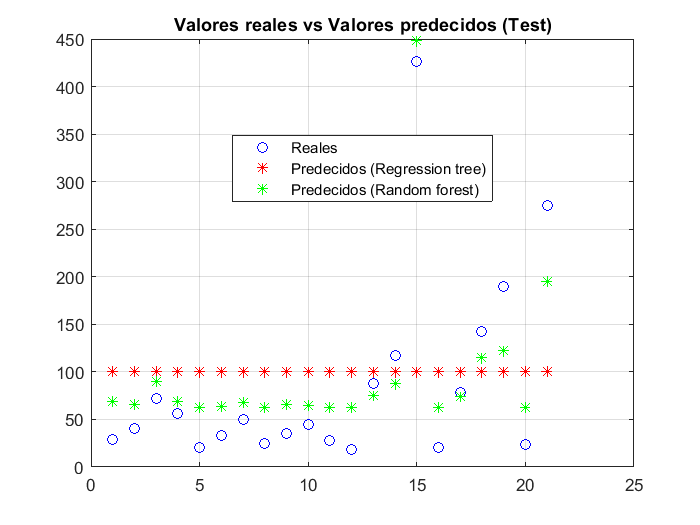


----------------------------------------------
Resultados para Fold Nro. 6
----------------------------------------------
Valor MSE (Regression tree) = 17363.0664
Valor MSE (Random forest) = 4423.5498
Diagrama de árbol de regresión

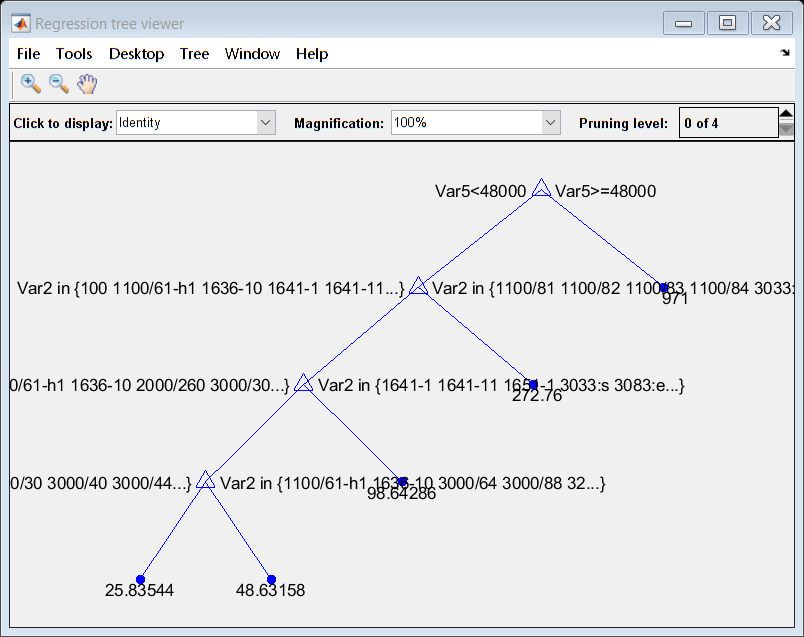

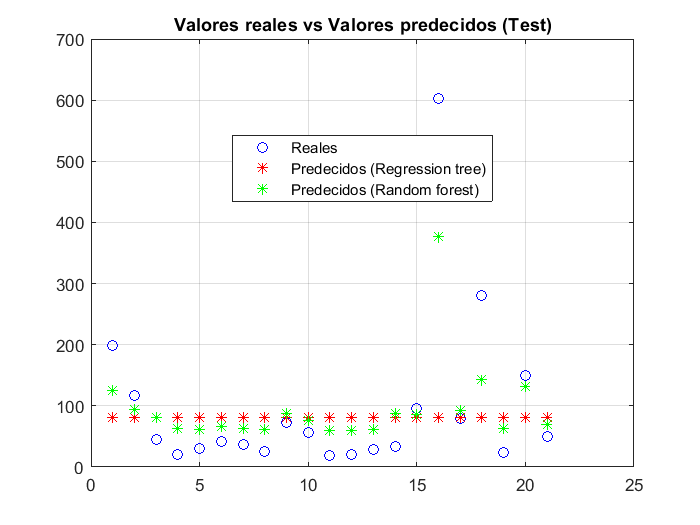


----------------------------------------------
Resultados para Fold Nro. 7
----------------------------------------------
Valor MSE (Regression tree) = 25499.1153
Valor MSE (Random forest) = 5979.0447
Diagrama de árbol de regresión

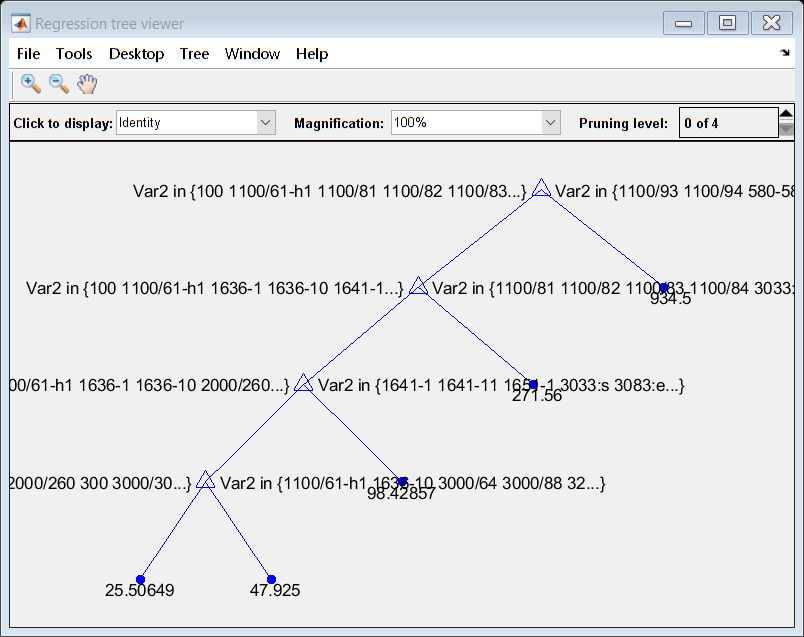

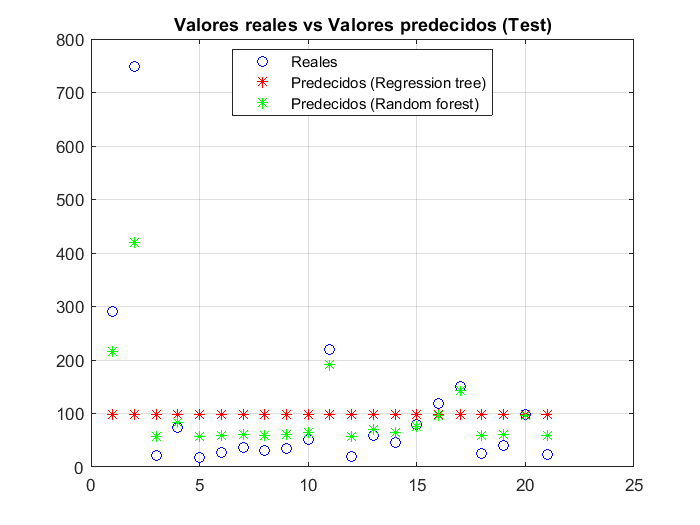


----------------------------------------------
Resultados para Fold Nro. 8
----------------------------------------------
Valor MSE (Regression tree) = 38603.7826
Valor MSE (Random forest) = 14759.4441
Diagrama de árbol de regresión

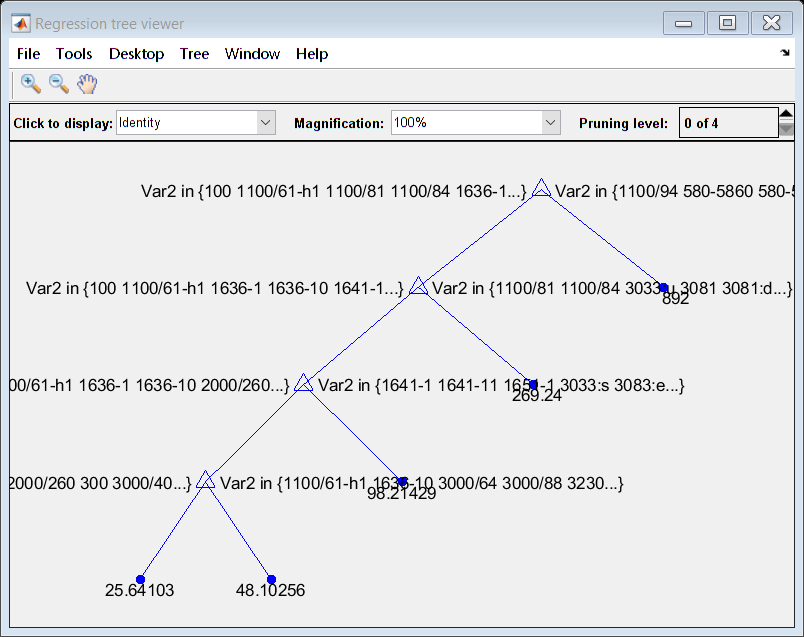

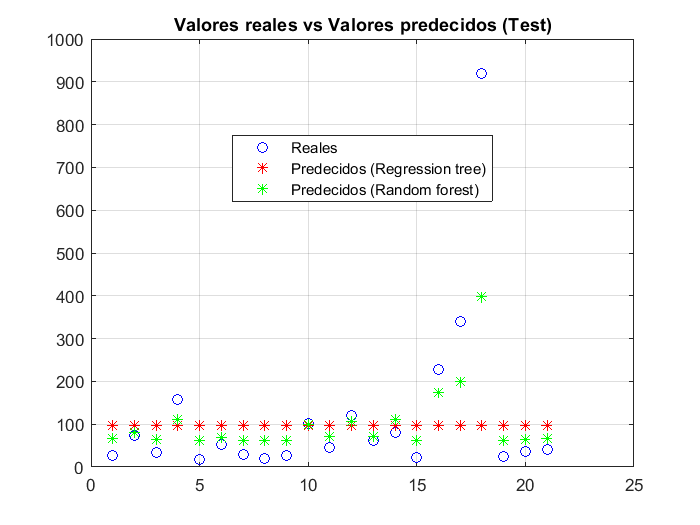


----------------------------------------------
Resultados para Fold Nro. 9
----------------------------------------------
Valor MSE (Regression tree) = 44069.6256
Valor MSE (Random forest) = 15782.3334
Diagrama de árbol de regresión

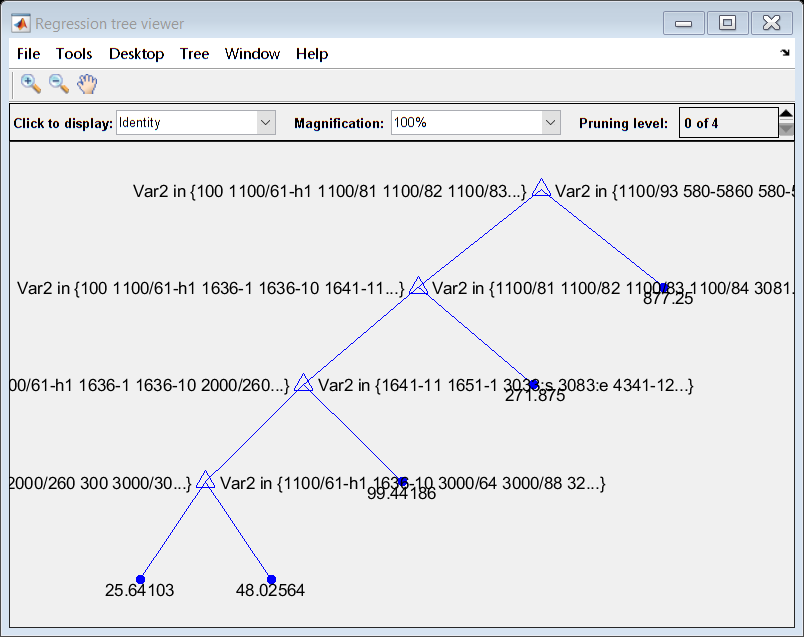

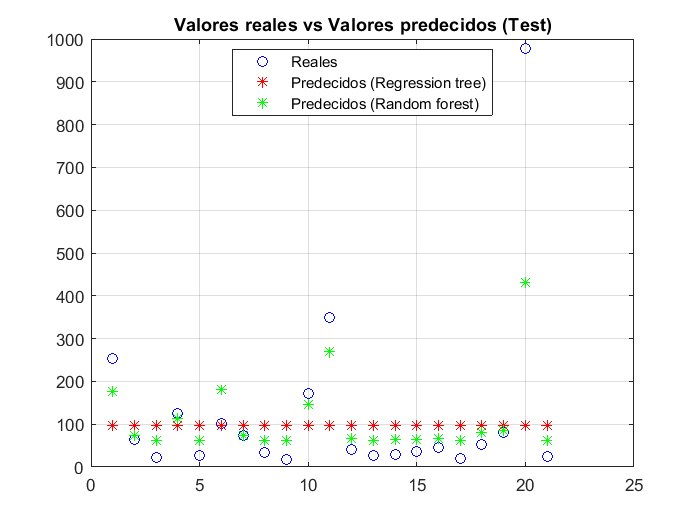


----------------------------------------------
Resultados para Fold Nro. 10
----------------------------------------------
Valor MSE (Regression tree) = 69479.9118
Valor MSE (Random forest) = 33386.6932
Diagrama de árbol de regresión

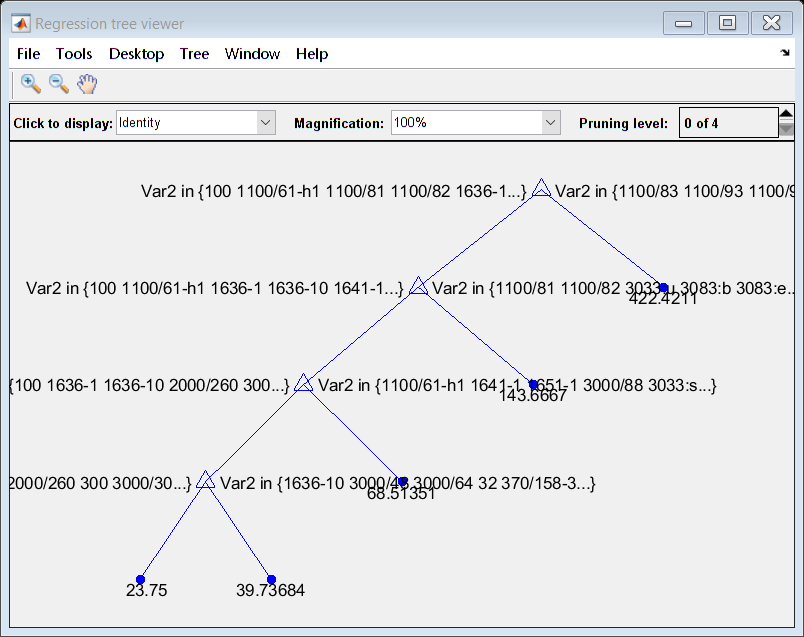

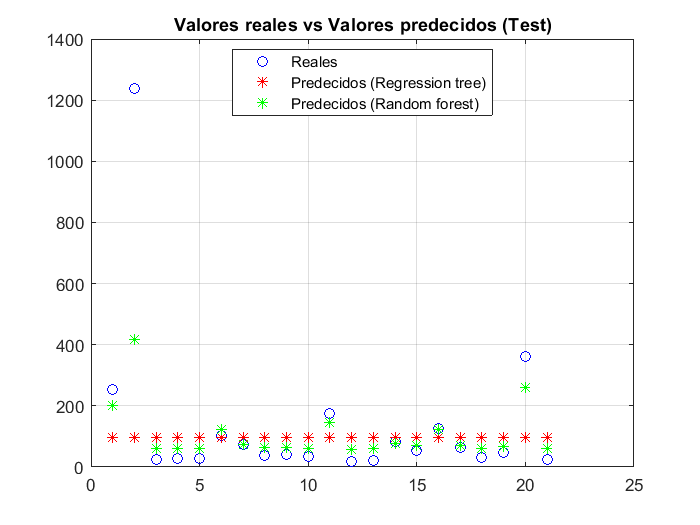


-----------------------------------------------------------------
Error Cuadrático Medio final (Regression tree) = 23868.0313
Error Cuadrático Medio final (Random forest) = 8165.3511
-----------------------------------------------------------------


T = readtable("machine.txt","ReadVariableNames",false);
X = T(:,1:9);
Y = table2array(T(:,10));
[mean_mse1, mean_mse1_rf] = calcularMSE(X, Y, 10, 100, true);

### Dataset carsmall

% Ejercicio 2: Dataset carsmall
rng(0);

fprintf("\n----------------------------------------------")


----------------------------------------------

fprintf("\nEjercicio 2: Dataset carsmall")


Ejercicio 2: Dataset carsmall

fprintf("\n----------------------------------------------")


----------------------------------------------


----------------------------------------------
Resultados para Fold Nro. 1
----------------------------------------------
Valor MSE (Regression tree) = 22.4046
Valor MSE (Random forest) = 14.9883
Diagrama de árbol de regresión

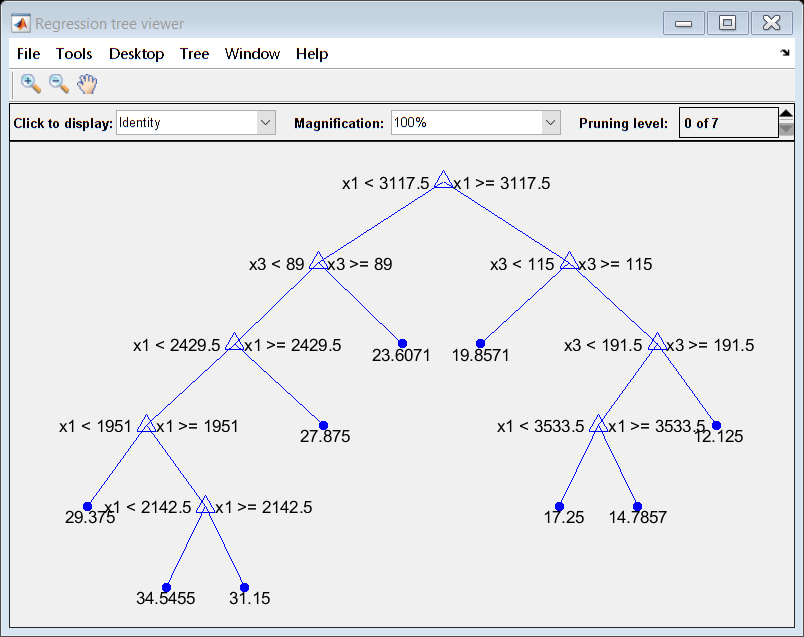

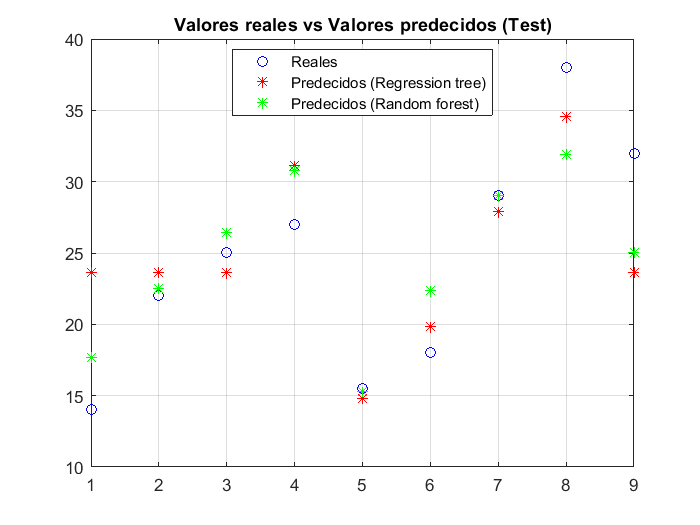


----------------------------------------------
Resultados para Fold Nro. 2
----------------------------------------------
Valor MSE (Regression tree) = 44.2292
Valor MSE (Random forest) = 30.5549
Diagrama de árbol de regresión

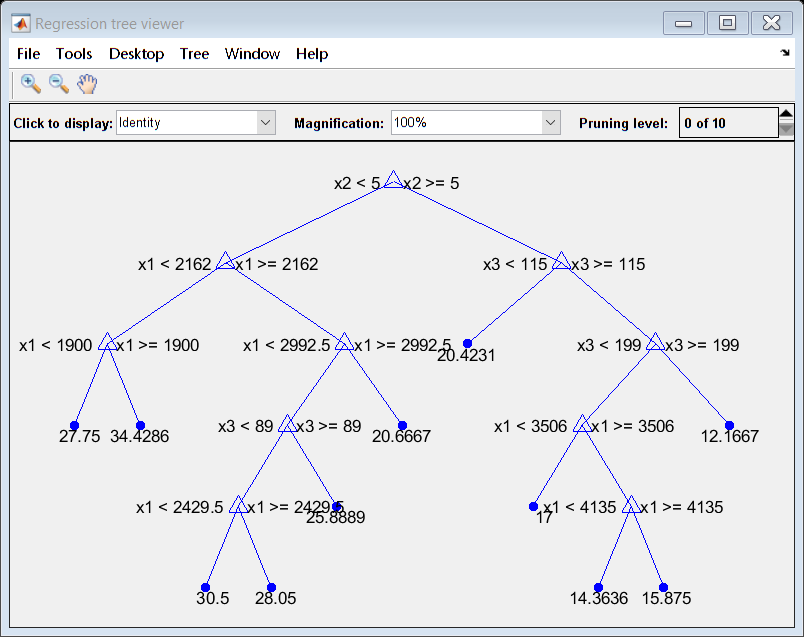

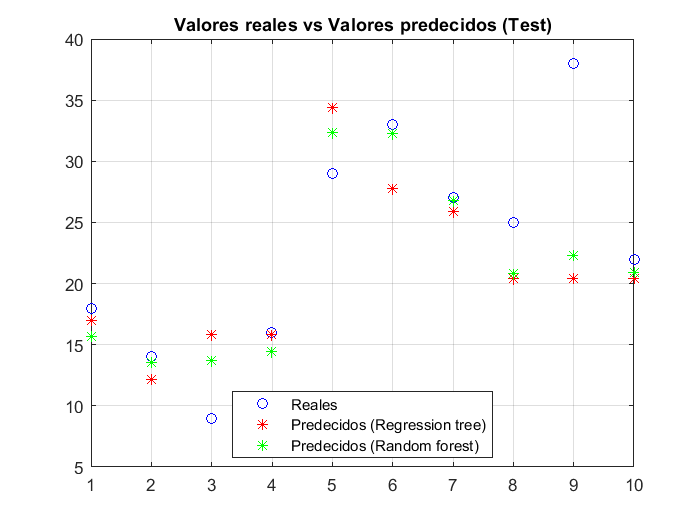


----------------------------------------------
Resultados para Fold Nro. 3
----------------------------------------------
Valor MSE (Regression tree) = 18.6867
Valor MSE (Random forest) = 8.7125
Diagrama de árbol de regresión

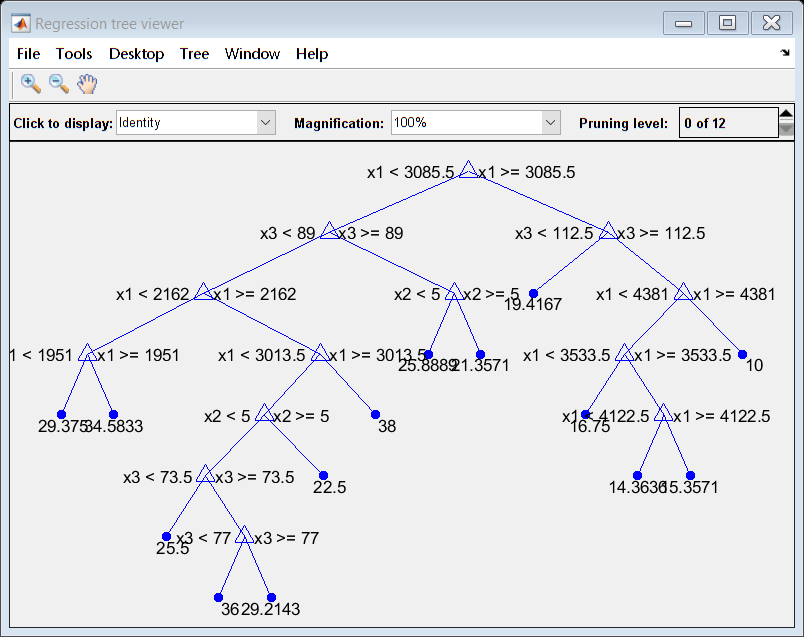

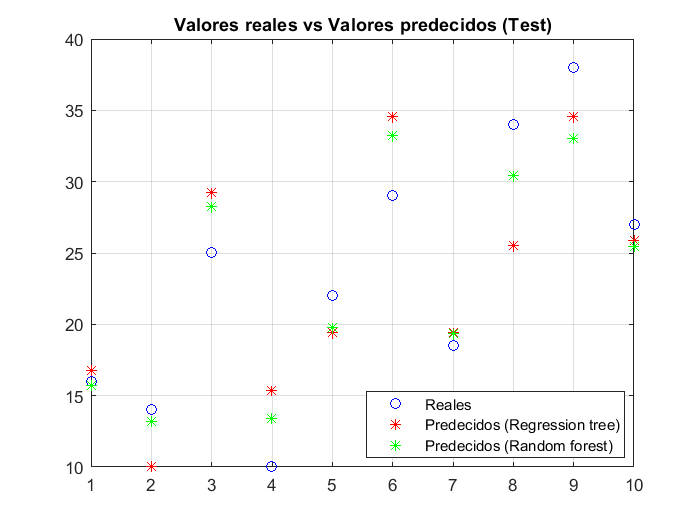


----------------------------------------------
Resultados para Fold Nro. 4
----------------------------------------------
Valor MSE (Regression tree) = 14.7443
Valor MSE (Random forest) = 13.2118
Diagrama de árbol de regresión

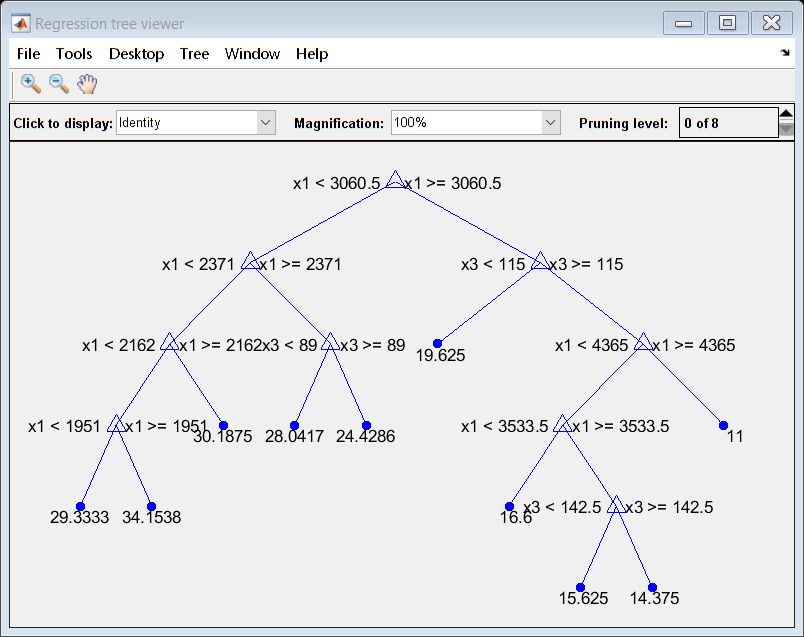

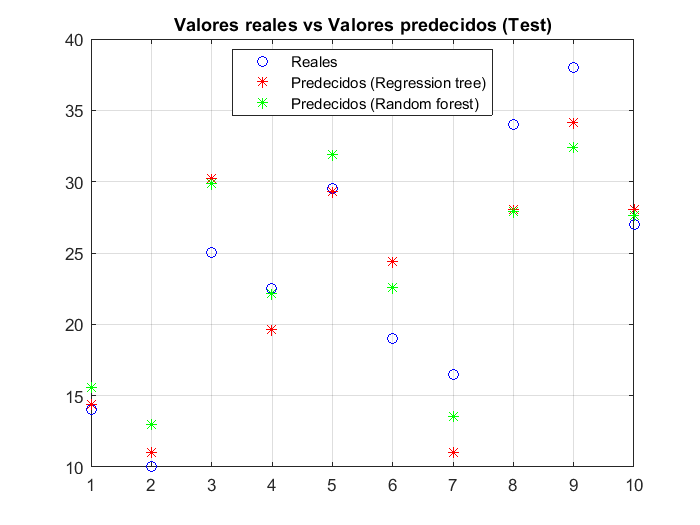


----------------------------------------------
Resultados para Fold Nro. 5
----------------------------------------------
Valor MSE (Regression tree) = 28.9077
Valor MSE (Random forest) = 25.6924
Diagrama de árbol de regresión

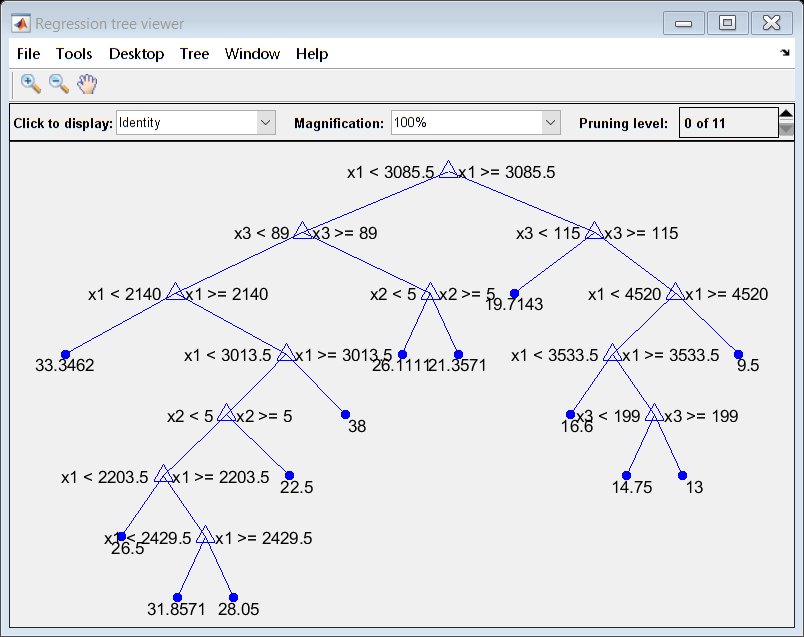

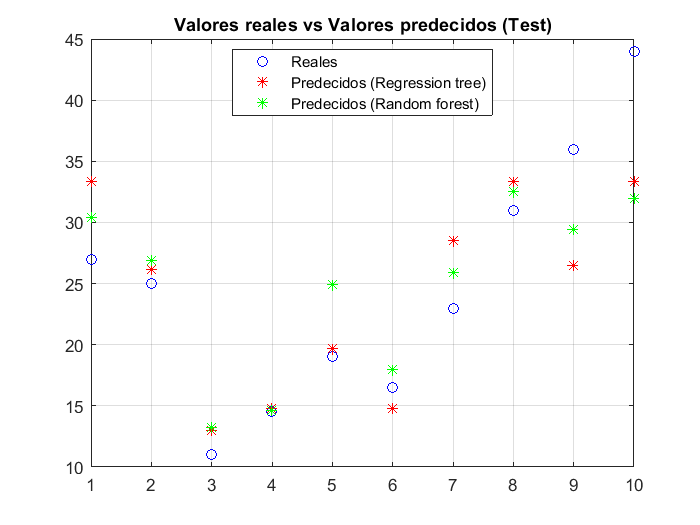


----------------------------------------------
Resultados para Fold Nro. 6
----------------------------------------------
Valor MSE (Regression tree) = 20.5011
Valor MSE (Random forest) = 9.9664
Diagrama de árbol de regresión

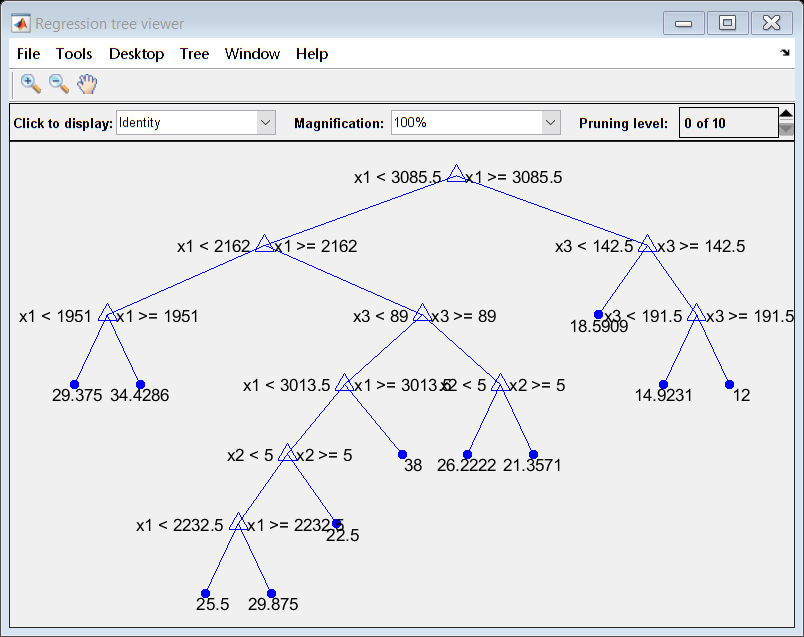

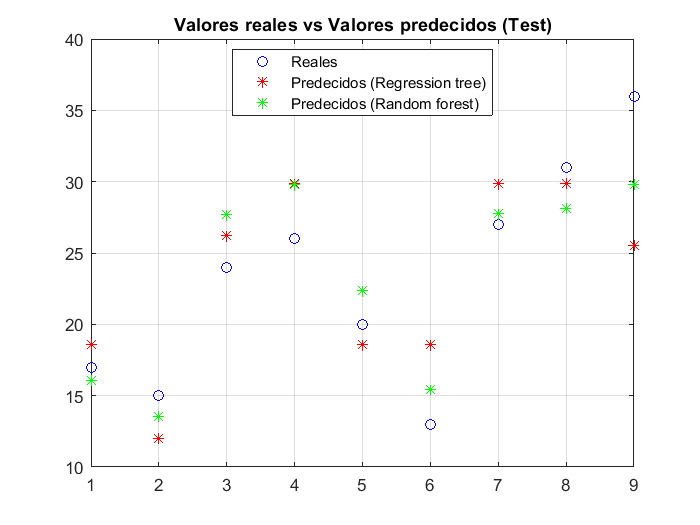


----------------------------------------------
Resultados para Fold Nro. 7
----------------------------------------------
Valor MSE (Regression tree) = 9.1458
Valor MSE (Random forest) = 5.6464
Diagrama de árbol de regresión

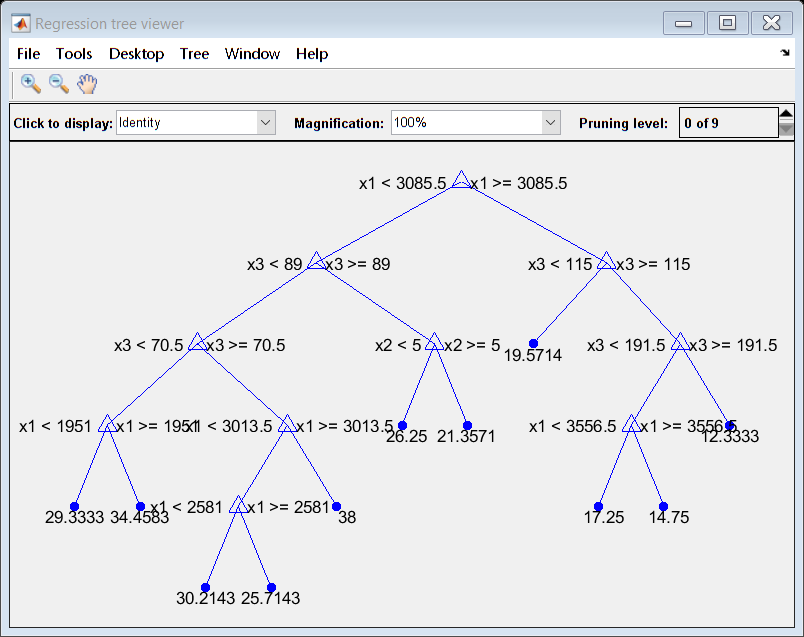

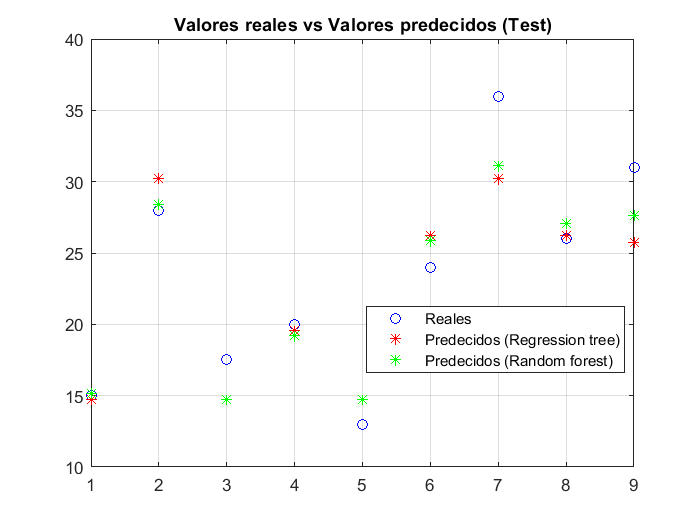


----------------------------------------------
Resultados para Fold Nro. 8
----------------------------------------------
Valor MSE (Regression tree) = 23.2017
Valor MSE (Random forest) = 7.0335
Diagrama de árbol de regresión

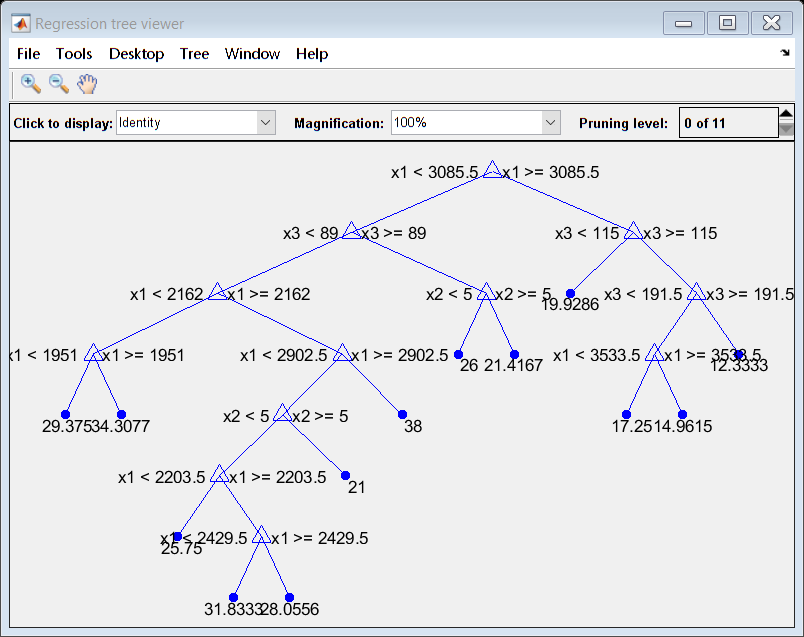

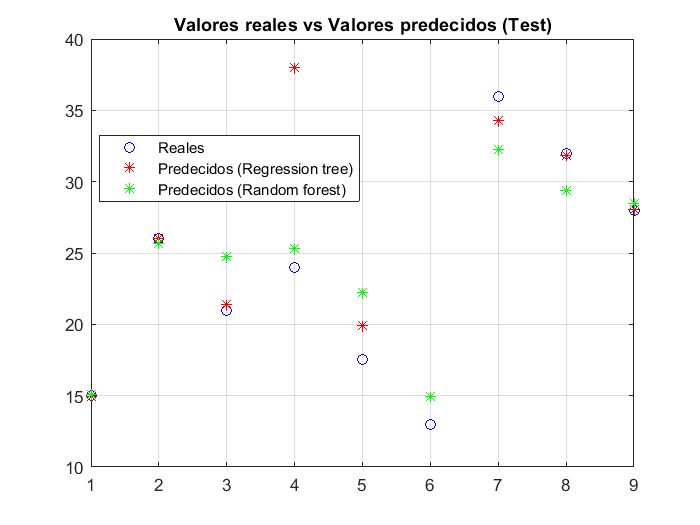


----------------------------------------------
Resultados para Fold Nro. 9
----------------------------------------------
Valor MSE (Regression tree) = 31.1984
Valor MSE (Random forest) = 17.9964
Diagrama de árbol de regresión

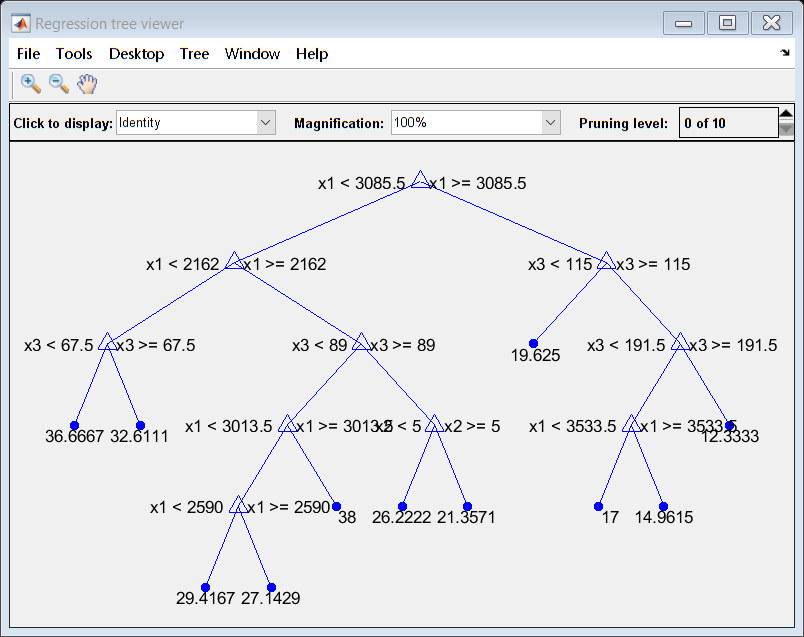

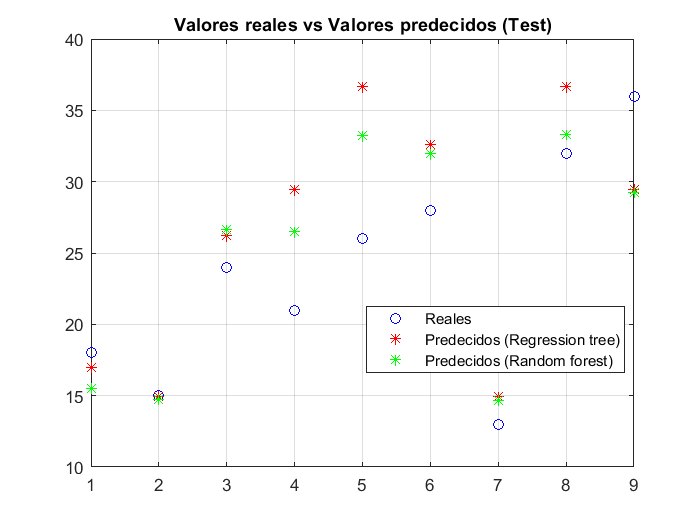


----------------------------------------------
Resultados para Fold Nro. 10
----------------------------------------------
Valor MSE (Regression tree) = 25.9988
Valor MSE (Random forest) = 16.4850
Diagrama de árbol de regresión

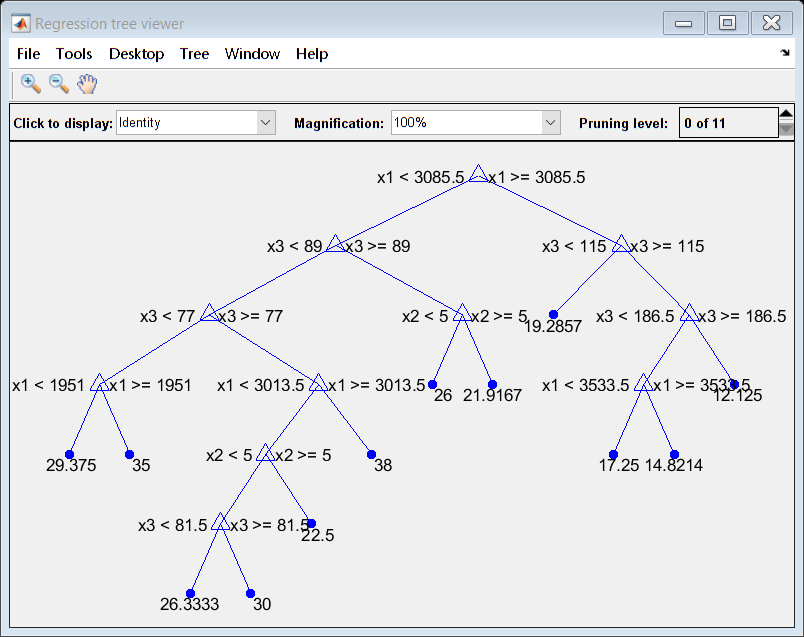

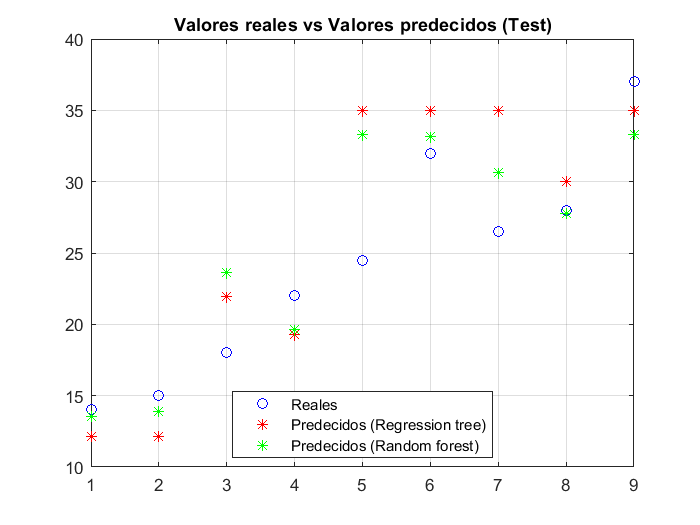


-----------------------------------------------------------------
Error Cuadrático Medio final (Regression tree) = 23.9018
Error Cuadrático Medio final (Random forest) = 15.0288
-----------------------------------------------------------------


load carsmall;
Com = (~isnan(MPG));
X = [Weight(Com),Cylinders(Com),Horsepower(Com)];
Y = MPG(Com);
[mean_mse2, mean_mse2_rf] = calcularMSE(X, Y, 10, 15, true);

### Dataset TratamientoRegresion

% Ejercicio 3: Dataset TratamientoRegresion
rng(0);

fprintf("\n----------------------------------------------")


----------------------------------------------

fprintf("\nEjercicio 3: Dataset TratamientoRegresion")


Ejercicio 3: Dataset TratamientoRegresion

fprintf("\n----------------------------------------------")


----------------------------------------------


----------------------------------------------
Resultados para Fold Nro. 1
----------------------------------------------
Valor MSE (Regression tree) = 1348.6111
Valor MSE (Random forest) = 1325.6636

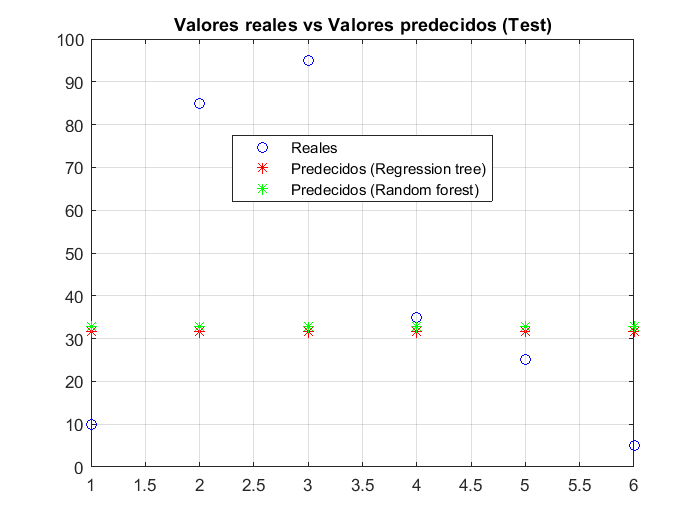


----------------------------------------------
Resultados para Fold Nro. 2
----------------------------------------------
Valor MSE (Regression tree) = 1047.9167
Valor MSE (Random forest) = 1037.3333

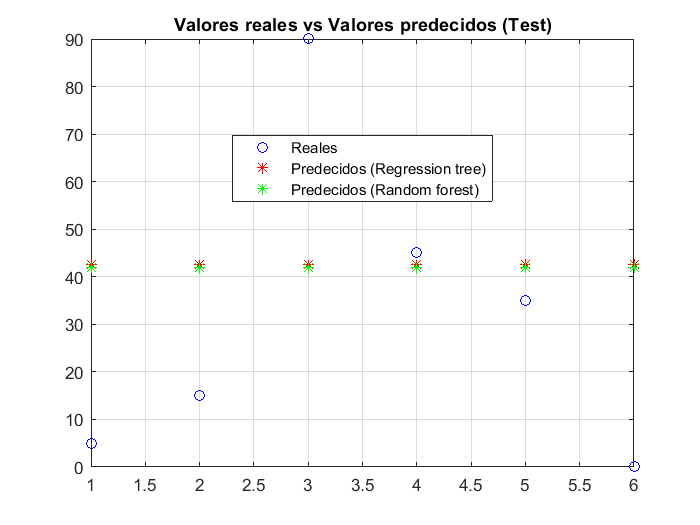


-----------------------------------------------------------------
Error Cuadrático Medio final (Regression tree) = 1198.2639
Error Cuadrático Medio final (Random forest) = 1181.4985
-----------------------------------------------------------------


T = readtable("Tratamientoregresion.xlsx", "Range","D6:E17","ReadVariableNames",false);
X = T(:,1);
Y = table2array(T(:,2));
[mean_mse3, mean_mse3_rf] = calcularMSE(X, Y, 2, 10, false);

Función general implementada:

function [mean_mse, mean_mse_rf] = calcularMSE(X, Y, k, minParentSize, graph)
    % Estrategia k-folding
    CVO = cvpartition(Y, "k", k);
    num_pruebas = CVO.NumTestSets;
    total_mse = 0;
    total_mse_rf = 0;
        
    for i = 1:num_pruebas
        fprintf("\n----------------------------------------------")
        fprintf("\nResultados para Fold Nro. %d", i)
        fprintf("\n----------------------------------------------")
        % Indices de training y test
        trIdx = CVO.training(i);
        teIdx = CVO.test(i);
        % Árbol de regresión
        tree = fitrtree(X(trIdx,:),Y(trIdx,:), "MinParentSize", minParentSize);
        % Vector de predicciones y cálculo de MSE (Regression tree)
        Ypred = predict(tree, X(teIdx,:));
        fold_mse = mse(Y(teIdx), Ypred);
        fprintf("\nValor MSE (Regression tree) = %.4f", fold_mse)
        total_mse = total_mse + fold_mse;
        % Random Forest
        RF = TreeBagger(200, X(trIdx,:), Y(trIdx,:), "Method", "regression", ...
            "OOBPrediction","On");
        Ypred_rf = RF.predict(X(teIdx,:));
        fold_mse_rf = mse(Y(teIdx), Ypred_rf);
        fprintf("\nValor MSE (Random forest) = %.4f", fold_mse_rf)
        total_mse_rf = total_mse_rf + fold_mse_rf;
        % Diagrama del árbol de regresión empleado
        if (graph)
            fprintf("\nDiagrama de árbol de regresión");
            view(tree,"mode","graph")
        end
        % Diagrama de valores reales contra valores predecidos
        figure;
        plot(Y(teIdx), "ob")
        hold on;
        plot(Ypred,"*r")
        hold on;
        plot(Ypred_rf, "*g")
        grid on;
        title("Valores reales vs Valores predecidos (Test)");
        legend("Reales", "Predecidos (Regression tree)", ...
        "Predecidos (Random forest)", 'Location', 'Best');
        hold off;
    end
    
    % Mean MSE para el ejercicio
    mean_mse = total_mse/num_pruebas;
    mean_mse_rf = total_mse_rf/num_pruebas;
    fprintf("\n-----------------------------------------------------------------")
    fprintf("\nError Cuadrático Medio final (Regression tree) = %.4f", mean_mse);
    fprintf("\nError Cuadrático Medio final (Random forest) = %.4f", mean_mse_rf);
    fprintf("\n-----------------------------------------------------------------")
end

### **Conclusión**

Se puede concluir que, de manera general, el método Random Forest ayudó a obtener mejores métricas en comparación con el árbol de regresión individual para los diferentes escenarios de regresión:

Para el caso del dataset Computer Hardware se obtuvo con un único árbol de decisión un MSE igual a  23.868,0313 mientras que con Random Forest se obtuvo un MSE igual a 8.165,3511.

Para el caso del dataset carsmall se obtuvo con un único arbol de decisión un MSE igual a 23,9018 y con Random Forest un MSE igual a 15,0288.

Finalmente, para el dataset TratamientoRegresion se obtuvo con un único árbol de regresión un MSE igual a 1.198,2639 mientras que con Random Forest el MSE obtenido fue de 1.181,4985.

Se puede concluir además que la mejora en la métrica obtenida se puede apreciar mucho mejor cuando se tienen varios datos para entrenamiento.